- García Muñoz Ari Manuel 

- Morales Flores Pedro Martín 

- Pérez Medina Rafael 

- Pineda Marin Ulises 

- Salazar Garcia Daniel 

# **Problema 2**

Existen otros tipos de funciones de membresía difusas. A las funciones membresía usuales (funciones del universo de discurso al intervalo [0 1] ), se les conoce como **funciones de membresía tipo-I** o **conjuntos difusos tipo-I**. Cuando no se tiene precisión sobre el grado de membresía se puede pensar en que se conoce el valor inferior y superior de membresía posibles, en este caso se tendrán *funciones de membresía evaluadas en un intervalo*, como lo muestra la Figura [1](https://rafneta.github.io/CN/R/R03.html#fig-ross2017_4_5), (Ross, 2017).

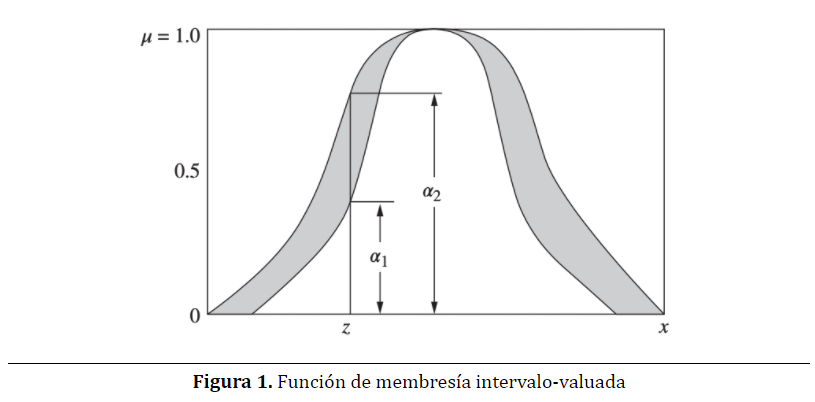 

En esta figura, para un elemento particular x=z el grado de membresía en un conjunto difuso  A(μA(z)), es expresado por el intervalo de membresía [α1 α2]. Este tipo de funciones de membresía son nombradas en la literatura como **conjuntos difusos tipo-II**. 

Así, todo lo que conoces hasta ahora sobre lógica difusa puede ser extendido utilizando *conjuntos difusos tipo-II*. El siguiente enlace: [Type-2 Fuzzy Inference Systems](https://www.mathworks.com/help/fuzzy/type-2-fuzzy-inference-systems.html) es una breve descripción de cómo se realiza en MATLAB inferencia difusa utilizando funciones de membresía tipo-II. 

En clase has revisado la implementación de un FIS tipo-I al siguiente [ejemplo](https://www.mathworks.com/help/fuzzy/fuzzy-pid-control-with-type-2-fis.html#FuzzyPIDControlWithType2FISExample-2). Reproduce la implementación que se encuentra en la misma [página](https://www.mathworks.com/help/fuzzy/fuzzy-pid-control-with-type-2-fis.html#FuzzyPIDControlWithType2FISExample-3) de dicho FIS utilizando funciones de membresía tipo-II. Adjunta un enlace a tu página html donde se encuentre la implementación. 

## Solución:

Lo primero es implementar  el FIS tipo-I para formar después el tipo-II.

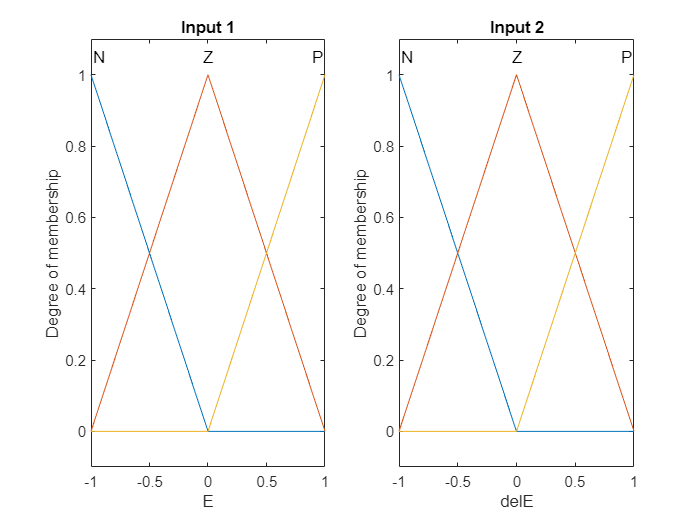

%Crear un FIS tipo-I usando sugfis
fis1 = sugfis();
%Añadir las varibales de entrada al FIS
fis1 = addInput(fis1,[-1 1],'Name','E');
fis1 = addInput(fis1,[-1 1],'Name','delE');
%Añadir las 3 funciones de membresisa a cada entrada; Cero(Z), Positivo(P)
%y Negativo(N).
fis1 = addMF(fis1,'E','trimf',[-2 -1 0],'Name','N');
fis1 = addMF(fis1,'E','trimf',[-1 0 1],'Name','Z');
fis1 = addMF(fis1,'E','trimf',[0 1 2],'Name','P');
fis1 = addMF(fis1,'delE','trimf',[-2 -1 0],'Name','N');
fis1 = addMF(fis1,'delE','trimf',[-1 0 1],'Name','Z');
fis1 = addMF(fis1,'delE','trimf',[0 1 2],'Name','P');
%Gráficar las funciones de membresia:
figure
subplot(1,2,1)
plotmf(fis1,'input',1)
title('Input 1')
subplot(1,2,2)
plotmf(fis1,'input',2)
title('Input 2')

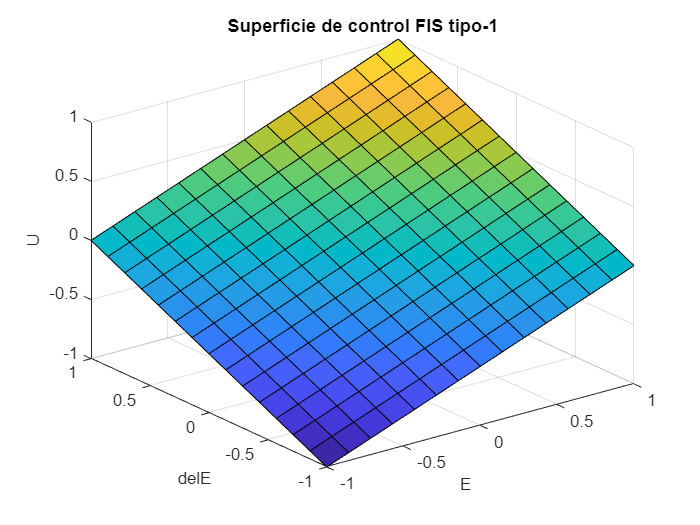

%La variable de salida del FIS:
fis1 = addOutput(fis1,[-1 1],'Name','U');
%Añade las constantes a la salida.
%Negativo Grande(NB), negativo mediano(NM), cero(Z), positivo mediano(PM) y
%positibo grande(PB)
fis1 = addMF(fis1,'U','constant',-1,'Name','NB');
fis1 = addMF(fis1,'U','constant',-0.5,'Name','NM');
fis1 = addMF(fis1,'U','constant',0,'Name','Z');
fis1 = addMF(fis1,'U','constant',0.5,'Name','PM');
fis1 = addMF(fis1,'U','constant',1,'Name','PB');
%Las reglas:
rules = [...
    "E==N & delE==N => U=NB"; ...
    "E==Z & delE==N => U=NM"; ...
    "E==P & delE==N => U=Z"; ...
    "E==N & delE==Z => U=NM"; ...
    "E==Z & delE==Z => U=Z"; ...
    "E==P & delE==Z => U=PM"; ...
    "E==N & delE==P => U=Z"; ...
    "E==Z & delE==P => U=PM"; ...
    "E==P & delE==P => U=PB" ...
    ];
fis1 = addRule(fis1,rules);
%Gráfica de la superficie de control.
figure
gensurf(fis1)
title('Superficie de control FIS tipo-1')

### **Resultados:**

Se crea a partir de lo definido anteriormente el FIS de tipo-II:

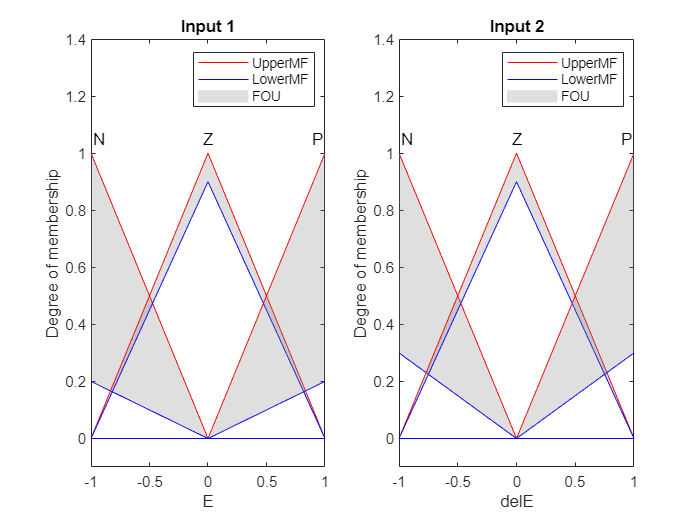

fis2 = convertToType2(fis1);
% El sistema de Sugeno tipo-2, fis2, usa las funciones de membresía tipo-2
% para las variables de entrada y las de tipo-1 son variables de salida.
%Se define el FOU para la entrada de las funciones de membresía definidas
%antes. Se establece el factor de escala minimo para cada función de
%membresia, en este caso se asignan a 0.
scale = [0.2 0.9 0.2;0.3 0.9 0.3];
for i = 1:length(fis2.Inputs)
    for j = 1:length(fis2.Inputs(i).MembershipFunctions)
        fis2.Inputs(i).MembershipFunctions(j).LowerLag = 0;
        fis2.Inputs(i).MembershipFunctions(j).LowerScale = scale(i,j);
    end
end
%Ploteamos las entradas:
figure
subplot(1,2,1)
plotmf(fis2,'input',1)
title('Input 1')
subplot(1,2,2)
plotmf(fis2,'input',2)
title('Input 2')

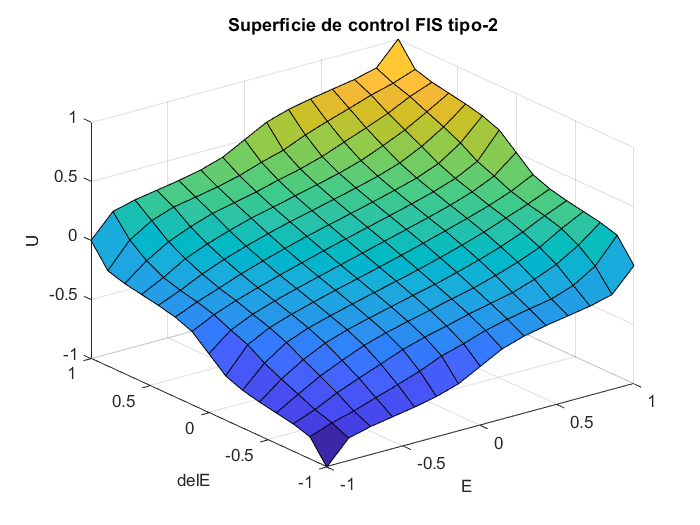

%Grafica de la superficie de control obtenida
figure
gensurf(fis2)
title('Superficie de control FIS tipo-2')